# QUICK START: Beam Steering Optimization

This script gets you started quickly with beam steering optimization for your 6-element line array

clear; close all; clc;

## Setup (using your existing parameters)

mm = 1000;
f = 4000; % Hz
c = 343.3; % Speed of sound [m/s]
lambda = c / f

lambda = 0.0858

point_distance = 0.01; % m
array_length_m = 1210 / mm;
No_linearray_elements = 6;
points_per_element = round((array_length_m / point_distance) / No_linearray_elements);

N_hor = 600;
N_ver = N_hor;
array_length = round(array_length_m / point_distance);
array_start = round((N_ver - array_length) / 2);
array_end = round((N_ver + array_length) / 2);

## Define array geometry

element_spacing = array_length_m / No_linearray_elements

element_spacing = 0.2017

element_positions = zeros(No_linearray_elements, 1);
for i = 1:No_linearray_elements
    element_positions(i) = (i - 0.5) * element_spacing - array_length_m/2;
end

array_geometry.element_positions = element_positions;
array_geometry.points_per_element = points_per_element;
array_geometry.point_distance = point_distance;
array_geometry.array_length = array_length_m;

## Simulation parameters

simulation_params.point_distance = point_distance;
simulation_params.N_hor = N_hor;
simulation_params.N_ver = N_ver;
simulation_params.No_linearray_elements = No_linearray_elements;
simulation_params.points_per_element = points_per_element;
simulation_params.array_start = array_start;
simulation_params.array_end = array_end;

## OPTION A: Fast Analytical Solution (good starting point)

fprintf('=== OPTION A: Analytical Solution (Fast) ===\n\n');

=== OPTION A: Analytical Solution (Fast) ===




target_angle = 15; % degrees
[delays_analytical, gains_analytical] = analytical_beam_steering(...
    target_angle, f, array_geometry,'chebyshev');
gain_usage_perc = 100 * sum(gains_analytical)/No_linearray_elements;

fprintf('Analytical delays (μs):\n');

Analytical delays (μs):


disp(delays_analytical' * 1e6);

 -380.0989 -228.0593  -76.0198   76.0198  228.0593  380.0989



fprintf('Analytical gains:\n');

Analytical gains:


disp(gains_analytical');

    0.2956    0.6837    1.0000    1.0000    0.6837    0.2956



fprintf('Gain usage:\t%.2f%%\n',gain_usage_perc);

Gain usage:	65.98%



% Calculate beam pattern
[angles, bp_analytical, DI] = calculate_beam_pattern(...
    delays_analytical, gains_analytical, f, array_geometry);
[~, max_idx] = max(bp_analytical);
fprintf('Achieved angle: %.2f° (target: %.1f°)\n', angles(max_idx), target_angle);

Achieved angle: -9.00° (target: 15.0°)


fprintf('Directivity Index: %.1f dB\n\n', DI);

Directivity Index: 38.5 dB



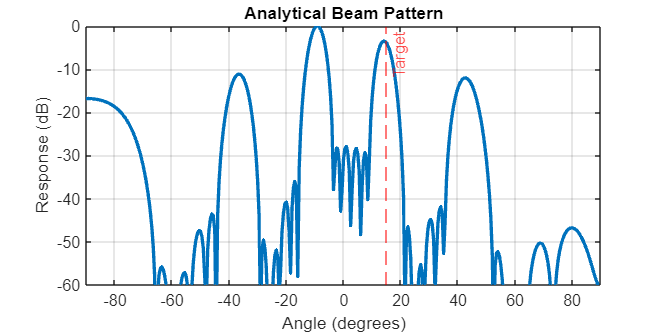


% Visualize
figure('Position', [100, 100, 800, 400]);
%subplot(2,1,1);
plot(angles, bp_analytical, 'LineWidth', 2);
grid on;
xlabel('Angle (degrees)');
ylabel('Response (dB)');
title('Analytical Beam Pattern');
xline(target_angle, 'r--', 'Target');
xlim([-90 90]);
ylim([-60 0]);

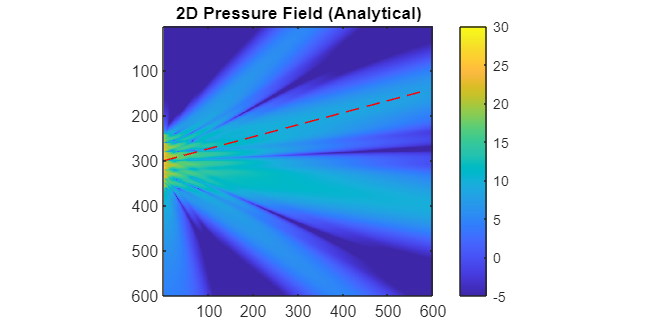


%subplot(2,1,2);

pf = simulate_with_optimized_params(delays_analytical, gains_analytical, f, simulation_params);
imagesc(pf, [-5 30]);
axis square;
hold on;
line([0 round(cos(target_angle * pi/180) * N_hor)], [N_ver/2 round(sin(-target_angle * pi/180) * N_ver) + N_ver/2],'Color','red','LineStyle','--');
colorbar;
title('2D Pressure Field (Analytical)');

## Optimization parameters (default values - adjust as needed)

optimization_params.mainlobe_width_deg = 5;
optimization_params.desired_beamwidth_deg = 25;
optimization_params.gain_uniformity_weight = 0.01;
optimization_params.total_gain_constraint = No_linearray_elements * 0.5;

optimization_params.weights.steering = 40; % 100;
optimization_params.weights.target_response = 40; % 60;
optimization_params.weights.sidelobe = 220 ;% 450
optimization_params.weights.beamwidth = 0.06; %1; % 0.5;
optimization_params.weights.gain_variation = 0.1; %0.1; % 0.1;

## OPTION B: Optimized Solution (slower but more accurate)

fprintf('\n=== OPTION B: Optimized Solution (Better Performance) ===\n\n');


=== OPTION B: Optimized Solution (Better Performance) ===




[delays_optimized, gains_optimized, results] = optimize_beam_steering(...
    target_angle, f, array_geometry, optimization_params);
gain_usage_perc = 100 * sum(gains_optimized)/No_linearray_elements;

fprintf('Optimized delays (μs):\n');

Optimized delays (μs):


disp(delays_optimized' * 1e6);

 -381.6968 -226.0029  -74.0780   74.0780  226.0126  381.6968



fprintf('Optimized gains:\n');

Optimized gains:


disp(gains_optimized');

    0.2956    0.6835    1.0000    1.0000    0.6835    0.2954



fprintf('Gain usage:\t%.2f%%\n',gain_usage_perc);

Gain usage:	65.97%


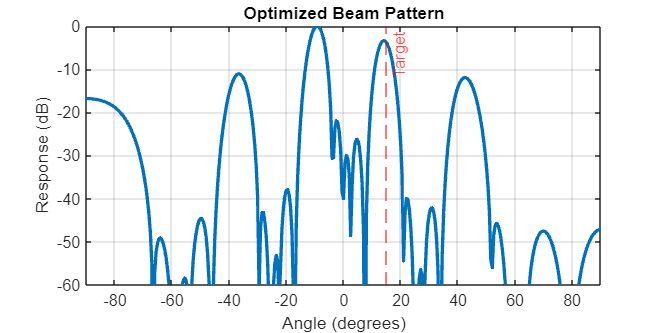


% Visualize
figure('Position', [100, 550, 800, 400]);
%subplot(1,2,1);
plot(results.angles, results.beam_pattern_dB, 'LineWidth', 2);
grid on;
xlabel('Angle (degrees)');
ylabel('Response (dB)');
title('Optimized Beam Pattern');
xline(target_angle, 'r--', 'Target');
xlim([-90 90]);
ylim([-60 0]);

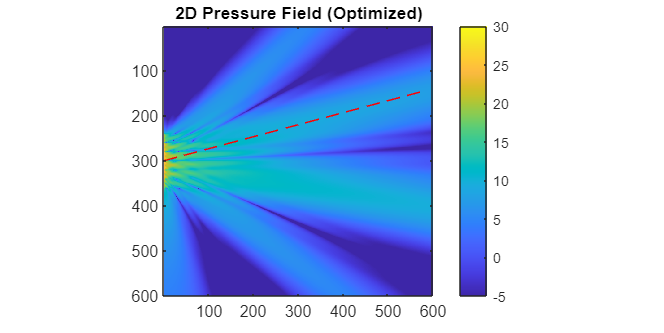


%subplot(1,2,2);
pf_opt = simulate_with_optimized_params(delays_optimized, gains_optimized, f, simulation_params);
imagesc(pf_opt, [-5 30]);
axis square;
hold on;
line([0 round(cos(target_angle * pi/180) * N_hor)], [N_ver/2 round(sin(-target_angle * pi/180) * N_ver) + N_ver/2],'Color','red','LineStyle','--');
colorbar;
title('2D Pressure Field (Optimized)');

## Save results for use in your main simulation

save('beam_steering_params.mat', 'delays_optimized', 'gains_optimized', ...
    'delays_analytical', 'gains_analytical', 'f', 'target_angle');

fprintf('\n✓ Results saved to: beam_steering_params.mat\n');


✓ Results saved to: beam_steering_params.mat


fprintf('✓ Use these delay and gain values in your main simulation!\n\n');

✓ Use these delay and gain values in your main simulation!



## How to use in your existing code:

fprintf('=== HOW TO USE IN YOUR SIMULATION ===\n\n');

=== HOW TO USE IN YOUR SIMULATION ===



fprintf('Replace your delay/gain assignment loop with:\n\n');

Replace your delay/gain assignment loop with:



fprintf('for a = 1:1:No_linearray_elements\n');

for a = 1:1:No_linearray_elements


fprintf('    for dy = 1:1:points_per_element\n');

    for dy = 1:1:points_per_element


fprintf('        idx = (a - 1) * points_per_element + dy + array_start;\n');

        idx = (a - 1) * points_per_element + dy + array_start;


fprintf('        delay_times(idx) = delays_optimized(a);\n');

        delay_times(idx) = delays_optimized(a);


fprintf('        gains(idx) = gains_optimized(a);\n');

        gains(idx) = gains_optimized(a);


fprintf('    end\n');

    end


fprintf('end\n\n');

end

